Generates the plot of Na-K pump current as a function of Ko

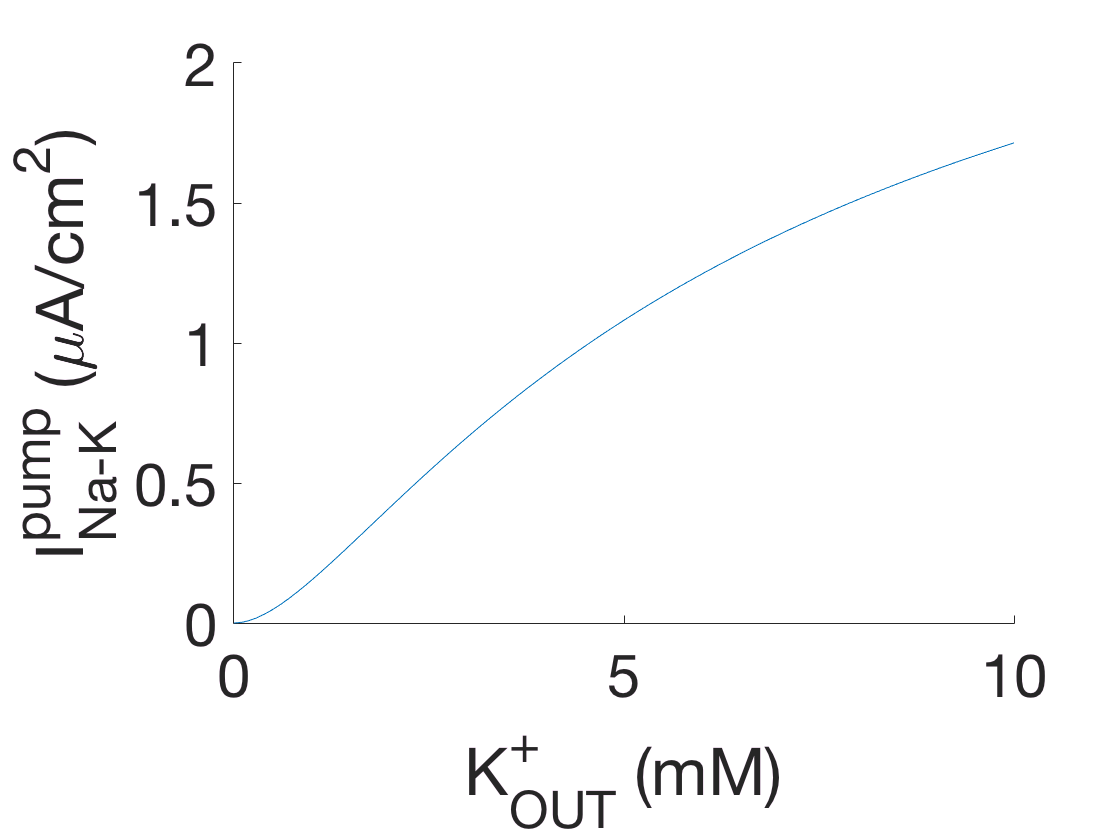

clear;

Koalpha_E=3.5;    % mM
Naialpha_E=20;    % mM
Imaxsoma_E=25;    % muA/cm^2
Nai_E=20;         % intra Na, mM

K_max=10;           % mM, maximal Ko concentration
K_step=0.1;        % step of Ko increase

K=0;               % mM, initial Ko concentration
K_min=K;
Ko(1)=K;
i=1;

while K<K_max 
 i=i+1;   
 
 K=K+K_step;
 Ko(i)=K;
 
 Ap=(1/((1+(Koalpha_E/Ko(i)))*(1+(Koalpha_E/Ko(i)))))*(1/((1+(Naialpha_E/Nai_E))*(1+(Naialpha_E/Nai_E))*(1+(Naialpha_E/Nai_E))));
 Ikpump=-2*Imaxsoma_E*Ap;
 INapump=3*Imaxsoma_E*Ap;
 
 INa_K(i)=Ikpump +INapump;
    
end

plot(Ko,INa_K);
box off;
set(gca,'Fontsize',30);
xlim ([K_min K_max]);
xlabel('K_{OUT}^+ (mM)');
ylabel('I_{Na-K}^{pump} (\muA/cm^2)');

Generates the plot corresponding to the Glial buffer as a funciton of extracellular potassium.

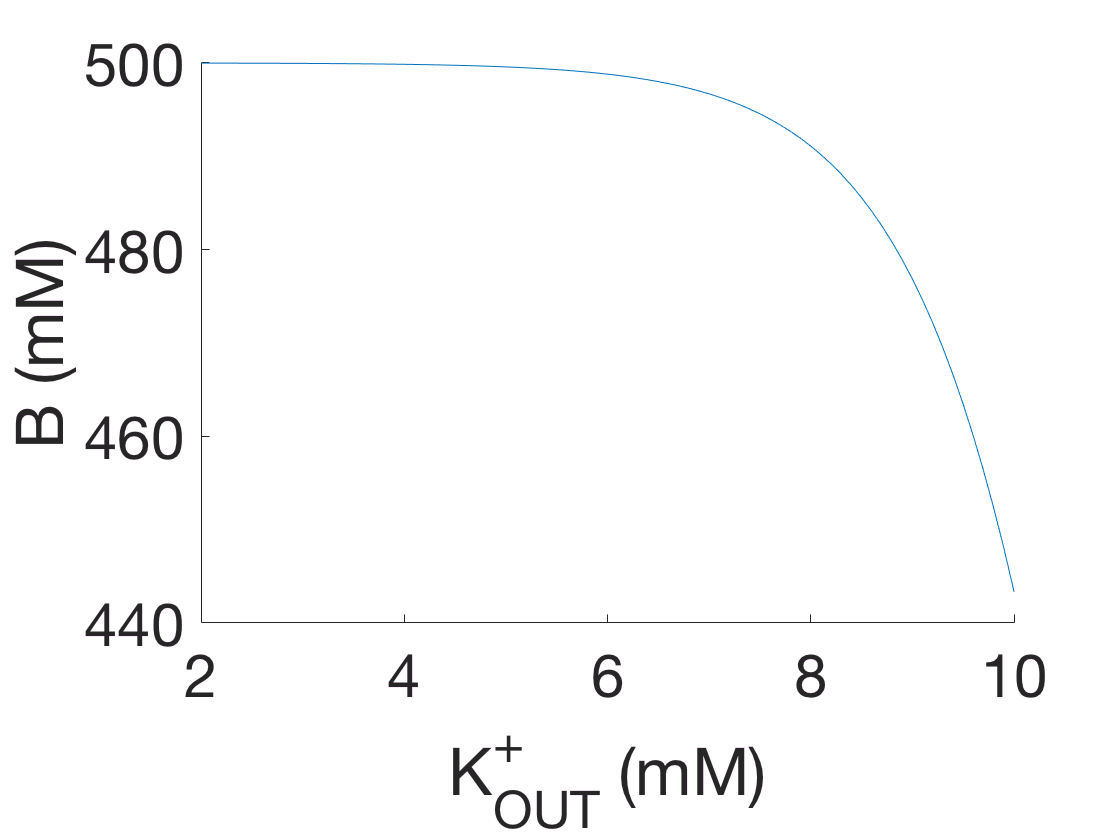

clear;

K_max=10;           % mM, maximal Ko concentration
K_step=0.1;        % step of Ko increase


Kothsoma_E=15;    % mM
koff_E=0.0008;    % 1/ mM / ms
K1n_E=1.0;        % 1/ mM
Bmax_E=500;       % mM

K=2;               % mM, initial Ko concentration
K_min=K;
Ko(1)=K;
i=1;

kon=koff_E/(1+exp((Ko(1)-Kothsoma_E)/(-1.15)));
Bs(1)=koff_E*Bmax_E/(kon*Ko(1)+koff_E);

G(1)=kon*Bs(1)*Ko(1) -koff_E*(Bmax_E-Bs(1));

while K<K_max 
 i=i+1;   
 
 K=K+K_step;
 Ko(i)=K;
 
 kon(i)=koff_E./(1+exp((Ko(i)-Kothsoma_E)/(-1.15)));
 Bs(i)=koff_E*Bmax_E./(kon(i)*Ko(i)+koff_E);

%G(i)=kon(i)*Bs(i)*Ko(i) -koff_E*(Bmax_E-Bs(i));    % gives chaotic map
 
end

plot(Ko,Bs);
box off;
set(gca,'Fontsize',30);
xlim ([K_min K_max]);
xlabel('K_{OUT}^+ (mM)');
ylabel('B (mM)');

This section computes and plots the current via IKCC2 as a function of extracellular potassium

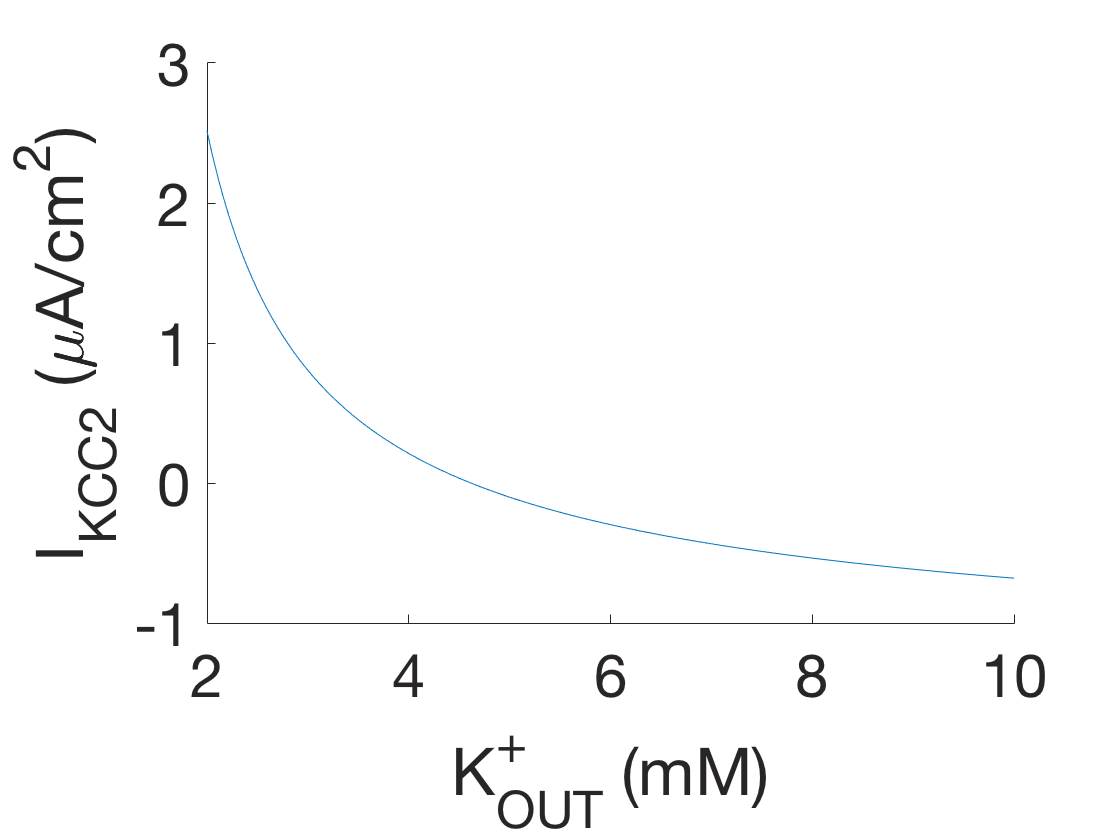

%clear;

K_max=10;           % mM, maximal Ko concentration
K_step=0.05;        % step of Ko increase

e0_E=26.6393;      % kT/F, in Nernst equation
Ki_E=150;         % intra K, mM
Cli=4;            % mM, peak at 12
Clo_E=130;        % mM
Vhalf_E=40;       % KCC2 1/2
Ikcc2_E=2;        % KCC2 max current
VCL=e0_E*log(Cli/Clo_E);

K=2;               % mM, initial Ko concentration
K_min=K;
Ko(1)=K;
i=1;

VKe(1)=e0_E*log(Ko(1)/Ki_E);
IKCC2(1)=Ikcc2_E*(VKe(1)-VCL)/((VKe(1)-VCL)+Vhalf_E);

while K<K_max 
 i=i+1;   
 
 K=K+K_step;
 Ko(i)=K;
 
 VKe=e0_E*log(Ko(i)/Ki_E); 
 IKCC2(i)=Ikcc2_E*(VKe-VCL)/((VKe-VCL)+Vhalf_E);
 
end

plot(Ko,-IKCC2);
box off;
set(gca,'Fontsize',30);
xlim ([2 K_max]);
xlabel('K_{OUT}^+ (mM)');
ylabel('I_{KCC2} (\muA/cm^2)');